%% Position trajectory design for quadcopter flip maneuver with geometric control
% Requirements: Optimization Toolbox, Symbolic Math Toolbox
%% Parameters of the Crazyflie 2.1
m = 0.028;
g = 9.81;
L = 0.046/sqrt(2);
J = diag([1.4e-5, 1.4e-5, 2.17e-5]); % inertia matrix
N = 432;  % number of discrete points

%% Reference trajectory for R
syms q0 tsym
q0 = -1.99./(1+exp(-20*(tsym-0.45)))+0.995;
dq0 = diff(q0,tsym);
q0_f = matlabFunction(q0);
dq0_f = matlabFunction(dq0);
clear q0 dq0
T = linspace(0,0.9,N);
q0 = q0_f(T);
dq0 = dq0_f(T);
R33 = zeros(N,1);
R13 = zeros(N,1);
R = zeros(N,3,3);
w = zeros(N,3);
dw = zeros(N,3);
eul = zeros(N,3);

for i=1:N
    R(i,:,:) = quat_to_rotm([q0(i), 0, sqrt(1-q0(i)^2), 0]);
    eul(i,:) = quat_to_eul([q0(i), 0, sqrt(1-q0(i)^2), 0]);
    R33(i) = R(i,3,3);
    R13(i) = R(i,1,3);
    w(i,2) = 2*dq0(i)/sqrt(1-q0(i)^2);
    if i>1
        dw(i,2) = (w(i,2)-w(i-1,2))*N/0.9;
    end
end

tau = zeros(N,1);
for i=1:N
    tau(i) = (J*dw(i,:)')'*[0; 1; 0];   % for the control input constraint
end
%% Quadratic program
Ts = 0.9/N; % sampling time
% Continuous SS model
Ac = [0,1,0,0; 0,0,0,0; 0,0,0,1; 0,0,0,0];
B = zeros(4,N);
for i = 1:N         % Discretization
    Bc = [0; R13(i)/m; 0; R33(i)/m];
    Disc = expm([Ac, Bc; zeros(1,5)]*Ts);
    B(:,i) = Disc(1:4,5);
end
A = Disc(1:4,1:4);
M = zeros(4,N);
x = zeros(4,N);
xr = [0; 0; 0.5*g*(Ts*N)^2; 0];     % final state reference
for i=1:N-1
    M(:,i) = A^(N-i)*B(:,i);
end
Q = [1, 0, 0, 0; 0, 0, 0, 0; 0, 0, 1, 0; 0, 0, 0, 0];
        % weight matrix for final state error

f = x(:,1)'*(A^N)'*Q*M - xr'*M;

H = M'*Q*M;

% Constraints for control input
D = zeros(2*N,N);
d = zeros(2*N,1);
for i = 1:N
    D(2*i-1,i) = -1;
    d(2*i-1) = -abs(tau(i))/L;
    D(2*i,i) = 1;
    d(2*i) = 0.64-abs(tau(i))/L;
end

Hc = zeros(4*N,N);
for i=1:N
    Mtemp = zeros(8*N,1);
    for j=1:N
        Mtemp(4*(j-1)+1:4*j) = A^(j-1)*B(:,i);
    end
    Hc(4*(i-1)+1:end,i) = Mtemp(1:4*(N-i+1),:);
end

ED = zeros(8*N,4*N);
EDpart = zeros(8,4);
EDpart(1,1) = 1; EDpart(3,3) = 1;
EDpart(5,1) = -1; EDpart(7,3) = -1;
for i=1:N
    ED(8*(i-1)+1:8*i,4*(i-1)+1:4*i) = EDpart;
end

% Contstraints for position in the x-z plane
xmin = -0.1; xmax = 0.6; zmin = -0.2; zmax = 0.5;
e = [xmax; 0; zmax; 0; -xmin; 0; -zmin; 0];
e = repmat(e,N,1);
for i=1:N
    e(8*(i-1)+3) = e(8*(i-1)+3)+0.5*g*(i*Ts)^2;
    e(8*(i-1)+7) = e(8*(i-1)+7)-0.5*g*(i*Ts)^2;
end

u = quadprog(H,f,[D;ED*Hc],[d;e]); % Quadratic problem solution


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


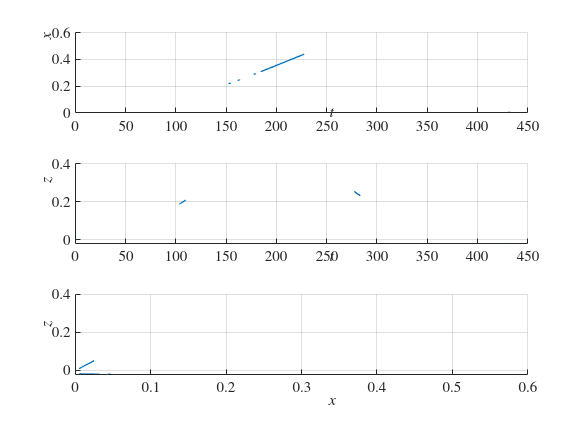


for i=1:N-1
    x(:,i+1) = A*x(:,i) + B(:,i)*u(i);
end

for i=1:N
    x(3,i) = x(3,i) - 0.5*g*(i*Ts)^2;
end
time = (1:N)';
pitch = eul(:,2);
pitch(175:259) = pi-pitch(175:259);
pitch(260:end) = pitch(260:end) + 2*pi;
%% Plots
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
set(groot,'defaultAxesFontSize',12);
set(groot,'defaultLineLineWidth',1);
figure(1)
subplot(3,1,1)
plot(time,x(1,:)')
box off
grid on
ylabel('$x$')
xlabel('$t$')
subplot(3,1,2)
plot(time,x(3,:)')
box off
grid on
ylabel('$z$')
xlabel('$t$')
subplot(3,1,3)
plot(time, pitch)
box off
grid on
ylabel('$\theta$')
xlabel('$t$')
% writematrix(u,'thrust.csv','Delimiter',',')
% writematrix([x(1,:)',x(3,:)',pitch],'geomref.csv','Delimiter',',')

figure(2)
plot(x(1,:),x(3,:))
box off
grid on
ylabel('$z$')
xlabel('$x$')


function R = quat_to_rotm(q)

R=[1-2*(q(2)^(2)+q(4)^(2)), 2*(q(2)*q(3)-q(4)*q(1)), 2*(q(2)*q(4)+q(3)*q(1)); 
    2*(q(2)*q(3)+q(4)*q(1)), 1-2*(q(2)^(2)+q(4)^(2)), 2*(q(3)*q(4)-q(2)*q(1)); 
    2*(q(2)*q(4)-q(3)*q(1)), 2*(q(3)*q(4)+q(2)*q(1)), 1-2*(q(2)^(2)+q(3)^(2))];
end

function ang = quat_to_eul(q)

ang=[atan2(2*(q(1)*q(2)+q(3)*q(4)),1-2*(q(2)^(3)+q(3)^(2)));
    asin(2*(q(1)*q(3)-q(4)*q(2)));
    atan2(2*(q(1)*q(4)+q(2)*q(3)),1-2*(q(3)^(2)+q(4)^(2)))];

end